# Lab 2: Building a Heart Rate Monitor (ENGR 029 SP23)

## Import and set up data/variables

% import data
ecg = importfile('ecgTrim.csv');
ecg.Times = ecg.Times - ecg.Times(1); % use relative rather than absolute times (so no negative times)

% set up variables
threshold = 0.5; % set to 0.5 volts for this example


## Plot unprocessed signal and signal after HPF

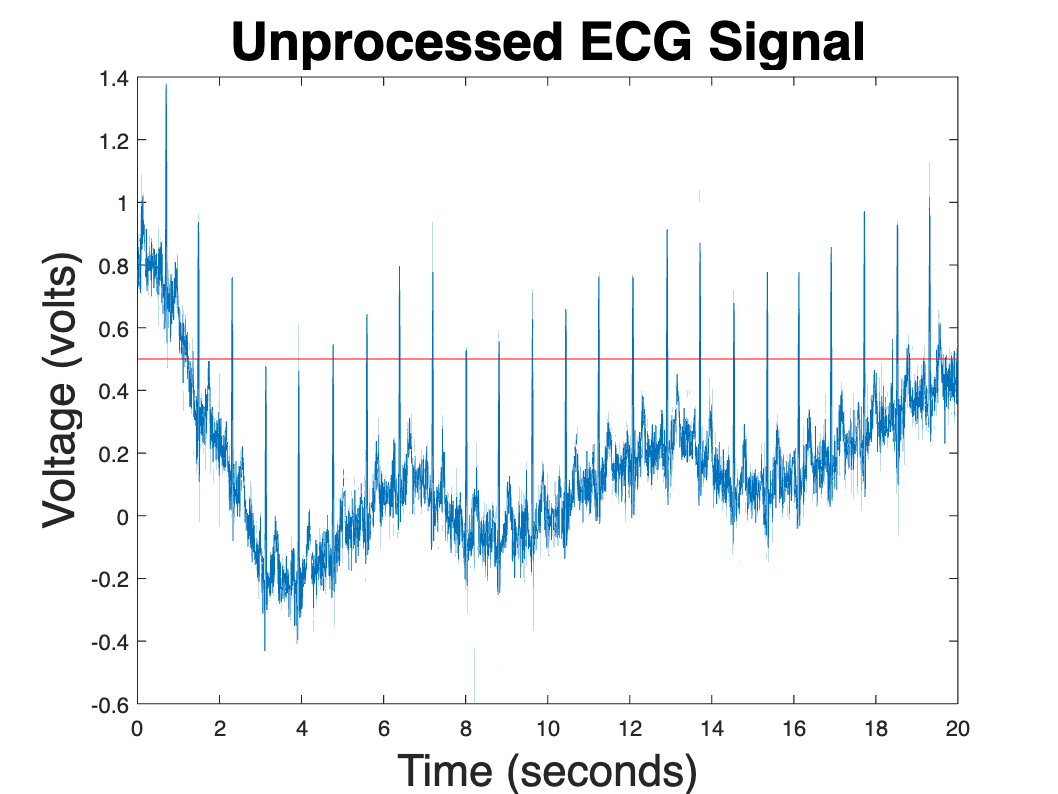

% plot unprocessed signal
figure
plot(ecg.Times,ecg.C1V);
title('Unprocessed ECG Signal','FontSize',24)
xlabel('Time (seconds)','FontSize',20)
ylabel('Voltage (volts)','FontSize',20)
hold on
line([ecg.Times(1) ecg.Times(end)],[threshold threshold],'Color','red'); % plot threshold line
hold off

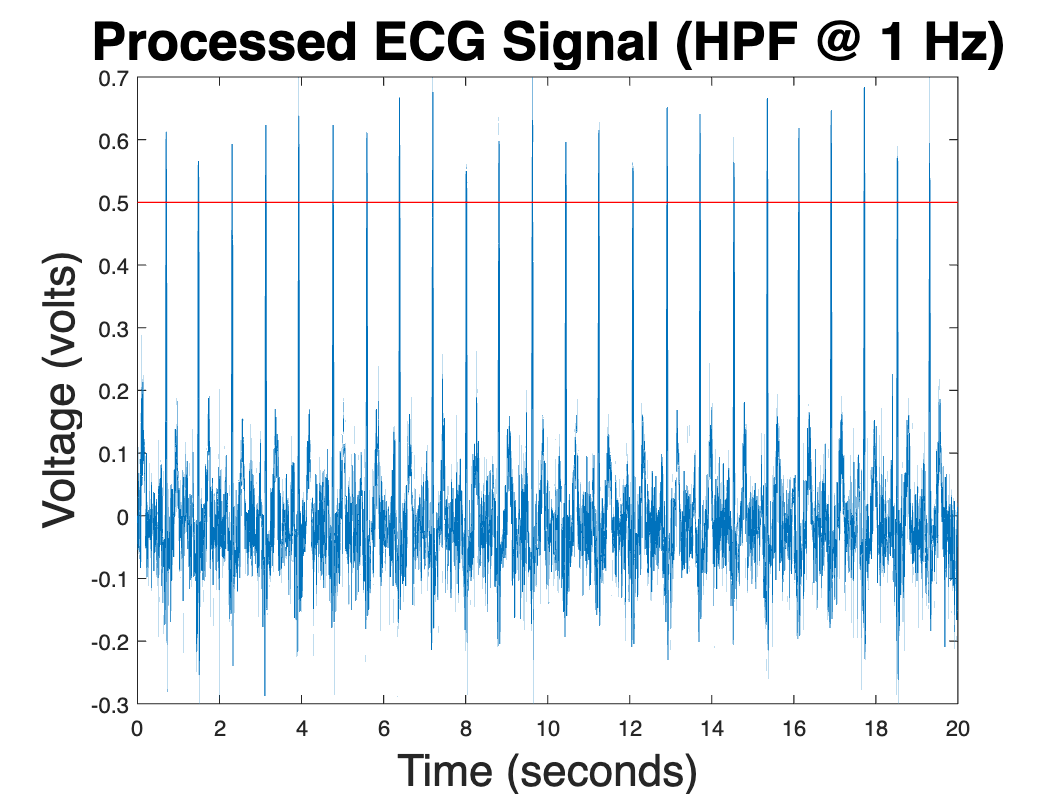


% plot processed signal (HPF of 1 Hz)
figure
Fs = 1/(ecg.Times(2) - ecg.Times(1));
wo = 1/(Fs/2);
b = fir1(500,wo,'High');
hpfECG = filtfilt(b,1,ecg.C1V);

plot(ecg.Times,hpfECG);
title('Processed ECG Signal (HPF @ 1 Hz)','FontSize',24)
xlabel('Time (seconds)','FontSize',20)
ylabel('Voltage (volts)','FontSize',20)
hold on
line([ecg.Times(1) ecg.Times(end)],[threshold threshold],'Color','red'); % plot threshold line
hold off

## Plot peaks and calculate IHR

This way is a lot longer and harder than the way you will do it, but here as an example and to help learn MATLAB syntax.

% find peaks, mark on figure, calculate and display IHR

above = find(hpfECG > threshold); % find indices above threshold

plot(ecg.Times,hpfECG);
title('HPF ECG w/ peaks (full dataset)','FontSize',24)
xlabel('Time (seconds)','FontSize',20)
ylabel('Voltage (volts)','FontSize',20)

hold on
line([ecg.Times(1) ecg.Times(end)],[0.5 0.5],'Color','red'); % plot threshold line
hold off

% initialize variables
onPeak = false; % keep track of whether we are above threshold or not
t1 = -1; % start our time as negative / invalid so we get two beats before first IHR

% iterate over indices above threshold, find and display peaks, calculate
% IHR
hold on
for j = 1:(length(above))

    % need special handling for last datapoint
    if (j ~= length(above))

        % assuming NOT last datapoint, check if we are on a peak
        if (above(j+1) - above(j) == 1)
            onPeak = true;
            
            % check which one value is bigger and save its index
            if (hpfECG(above(j)) < hpfECG(above(j+1)))
                maxIndex = j+1;
            else
                maxIndex = j;
            end
    
        % end of peak or no peak
        else
            % if a single datapoint above threshold, set maxIndex to
            % current index
            if ~onPeak
                maxIndex = j;
            end
    
            % plot peak
            plot(ecg.Times(above(maxIndex)),hpfECG(above(maxIndex)),'o','Color','red');
            onPeak = false;

            % calculate IHR
            % if t1 > 0, use t2 and t1 to calculate IHR
            if (t1 >= 0)
                t2 = ecg.Times(above(maxIndex));
                IHR = ihr(t1,t2)
                t1 = t2;
            
            % otherwise initialize t1
            else
                t1 = ecg.Times(above(maxIndex));
            end
    
        end

    % handling for last datapoint
    else
        % if solo last datapoint, set max to j, otherwise, use existing
        % max
        if ~onPeak
            maxIndex = j;
        end

        % plot peak and calculate IHR
        plot(ecg.Times(above(maxIndex)),hpfECG(above(maxIndex)),'o')
        
        if (t1 >= 0)
                t2 = ecg.Times(above(maxIndex));
                IHR = ihr(t1, t2);
                t1 = t2;
        else
            t1 = ecg.Times(above(maxIndex));
        end
        
    end
    
end

IHR = 76.1905

IHR = 73.2824

IHR = 72.7273

IHR = 75.0000

IHR = 71.6418

IHR = 72.7273

IHR = 75.5906

IHR = 73.8462

IHR = 73.2824

IHR = 75.5906

IHR = 73.2824

IHR = 73.8462

IHR = 74.4186

IHR = 72.7273

IHR = 71.6418

IHR = 75.0000

IHR = 72.7273

IHR = 73.2824

IHR = 78.0488

IHR = 76.1905

IHR = 74.4186

IHR = 74.4186

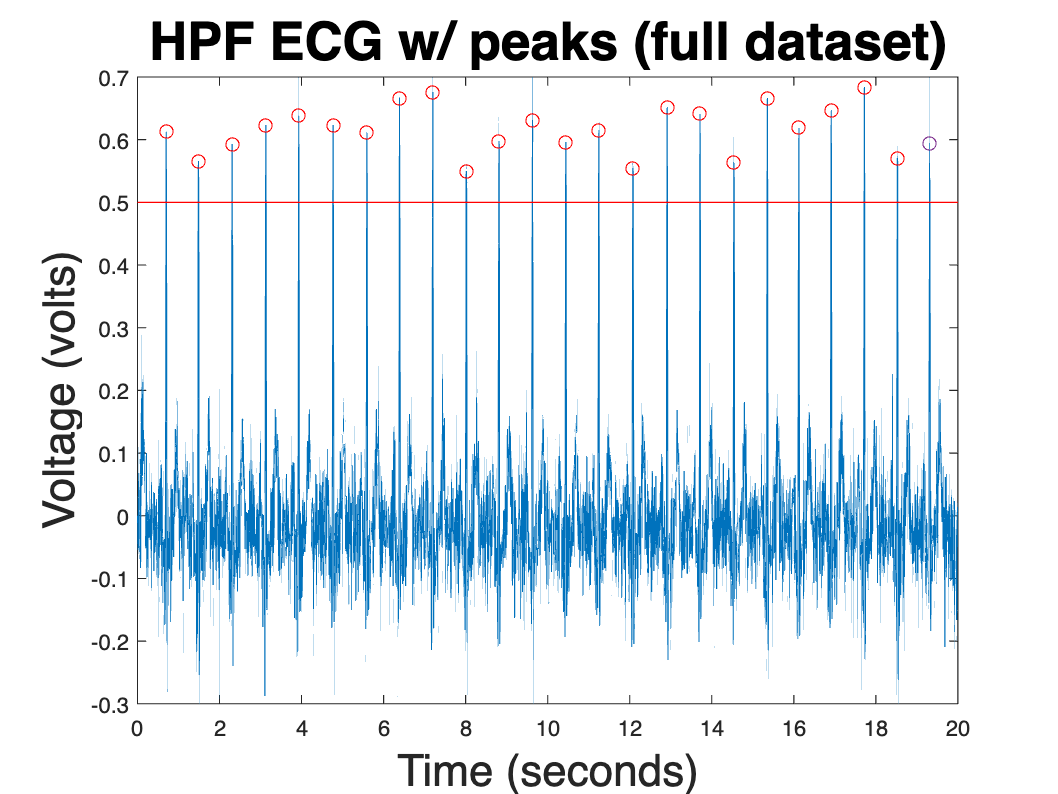


hold off

## Your Job: Write A Shorter Algorithm To Calculate Same IHRs As Above

Suggestion: keep track of the index when the signal goes above the threshold; when it falls below the threshold, plot it and calculate IHR. Your code will need to account for edge cases like what to do when the first beat is detected, but you can add that later once you get the basics to work.

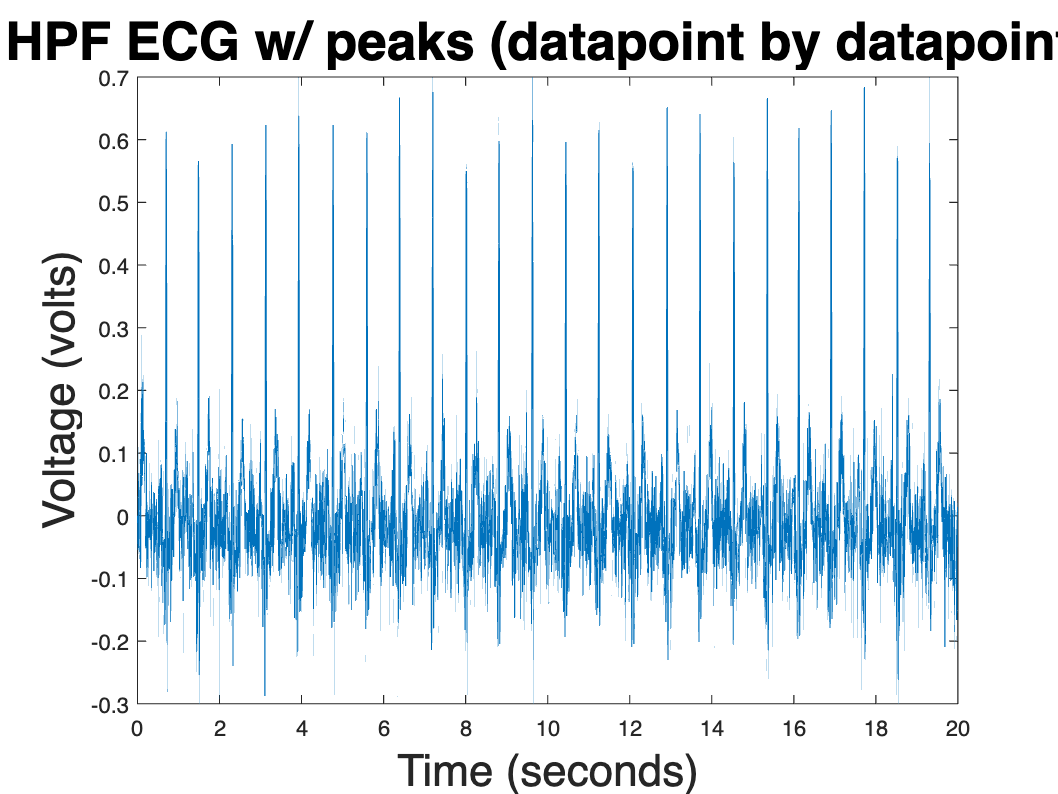

t1 = -1; % initialize time to a negative number to show it is unused
onPeak = false; % keep track of whether or not we are above the threshold or not
maxIndex = 1; % keep track of the index of our peak
calculated = true; % keep track of whether or not we've calculated IHR for a given peak

figure
plot(ecg.Times,hpfECG);
title('HPF ECG w/ peaks (datapoint by datapoint)','FontSize',24)
xlabel('Time (seconds)','FontSize',20)
ylabel('Voltage (volts)','FontSize',20)

hold on

% iterate over the data one index at a time; assume you only have access to
% information at the current timestep (i.e. no looking at j+1 or j-1), 
% but you have maxIndex, calculated, onPeak, and t1/t2. 
% This will translate best to the microcontroller setup.

for j = 1:length(ecg.Times)

    % if our signal is above the threshold, update maxIndex, onPeak,
    % calculated accordingly
    if (hpfECG(j) > threshold)
        
    % YOUR CODE HERE


    % if our signal is below the threshold, update onPeak, calculated
    % accordingly, and decide whether or not to plot and calculate IHR
    else
        
    % YOUR CODE HERE
    
    
    
    end

end

hold off

## Helper functions

Feel free to add any additional functions here, but they aren't necessary.

Returns heartRate in beats per minute.

function heartRate = ihr(t1,t2)
    heartRate = 1/(t2 - t1)*60;
end
